# Demo:  CSI Tracking with the NR CSI-RS

The 5G NR standard has a powerful set of reference signals from which the UE can monitor the channel quality.  These signals are called the *channel state indication reference signals* or CSI-RS.  The CSI-RS have many uses including link adaptation, beam management and inter-cell interference management.  In this demo, we will just look at using these reference signals for measuring the SNR and channel capacity on some simple single antenna channel.

In going through this demo, you will learn to:

- Configure the CSI-RS resources with MATLAB's 5G Toolbox configuration command `nrCSIRSConfig`. 

- Allocate zero power (ZP) and non-zero power (NZP) CSI-RS and visualize the allocation on an OFDM grid

- Simulate the CSI-RS transmission on a frequency-domain channel.

- Measure the channel quality using either NZP and ZP CSI-RS or jut NZP CSI-RS.

- Visualize the effect of the CSI-RS periodicity

Some of this demo is taken from [https://www.mathworks.com/help/5g/ug/5g-nr-csi-rs-measurements.html](https://www.mathworks.com/help/5g/ug/5g-nr-csi-rs-measurements.html)

## Configuring the CSI-RS

Like many channels in the 5G NR standard, the CSI-RS resources are highly configurable to trade off channel estimation accuracy with overhead.  We will illustrate for a channel with the following parameters. 

fc = 2.3e9;              % Carrier frequency
SubcarrierSpacing = 15;  % SCS in kHZ
NRB = 51;  % number of resource blocks
carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);

The bandwidth for this channel is approximately 10 MHz.

numScPerRB = 12;
bw = NRB*SubcarrierSpacing*numScPerRB;
fprintf('Bandwidth = %7.2f MHz\n', bw/1e3);

Bandwidth =    9.18 MHz


The CSI-RS are allocated in multiple resources.  In this configuration, we will set up two resources:

-  CSI-RS 0:  A zero power (ZP) CSI-RS to measure interference

-  CSI-RS 1:  A non-zero power (NZP)  CSI-RS to measure the channel strength

This configuration is excessive.  As we will see below, with some simple tricks we can just use the NZP resource.   Note:  You must allocate the ZP CSI-RS first.

csirs = nrCSIRSConfig();
% CSI-RS resource             #0       #1
csirs.CSIRSType           = {'zp', 'nzp'};

% Periodicity
% [period offset] for each CSI-RS resource.  The period is in slots.
% So, in this case, we are allocating these resources once per 10ms
csirs.CSIRSPeriod         = {[10,0], [10,0]};

% Row from TS 38.211 Section 7.4.1.5.  
% Row 1 is for single port
csirs.RowNumber           = [1, 1];    

% Density = 3 number of REs per RB
csirs.Density             = {'three', 'three'};

% Symbol location within the RB
csirs.SymbolLocations     = {6, 8};

% Subcarrier offset
csirs.SubcarrierLocations = {0, 0};

% Measurement bandwidth in terms of number of resource blocks
csirs.NumRB               = [NRB, NRB]; 

## Visualizing the CSI-RS allocation

We next visualize the allocation on the OFDM grid on some slot.  From the `csirs.CSIRSPeriod` field, we have configured the CSI-RS on slots 0, 10, 20, ... within a frame.  So, we get the indices and symbols for the CSI-RS on one of these frames as follows.

% Set the slot number within the frame
carrierConfig.NSlot = 0;

% Get the indices and complex symbols
[ind, info] = nrCSIRSIndices(carrierConfig,csirs,'OutputResourceFormat','cell');
sym = nrCSIRS(carrierConfig,csirs,'OutputResourceFormat','cell');


Next we populate a grid with indicators for each CSI-RS resource.  

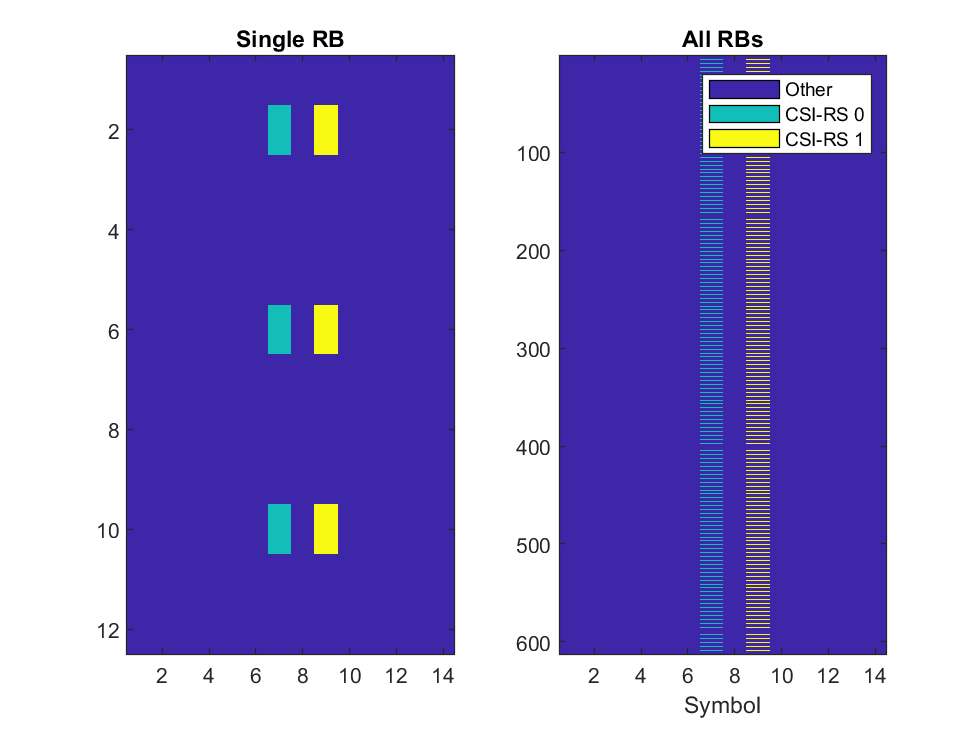

NumPorts = 1;
gridInd = nrResourceGrid(carrierConfig, NumPorts);

ncsi = length(ind);
legStr = cell(ncsi+1,1);
legStr{1} = 'Other';
for i = 1:ncsi
    legStr{i+1} = sprintf('CSI-RS %d', i-1);
    gridInd(ind{i})=i;
end

% Plot the locations for one RB
subplot(1,2,1);
indRB = 10;
numScPerRB = 12;
I = (indRB*numScPerRB:(indRB+1)*numScPerRB-1);
plotChan(gridInd(I,:));
title('Single RB');

% Plot the locations for all RBs
subplot(1,2,2);
xlabel('Symbol');
ylabel('Sub-carrier');

plotChan(gridInd, legStr);
title('All RBs');
xlabel('Symbol');

## Create a Channel

To simulate the CSI-RS measurement we create a simple three tap channel in frequency domain.

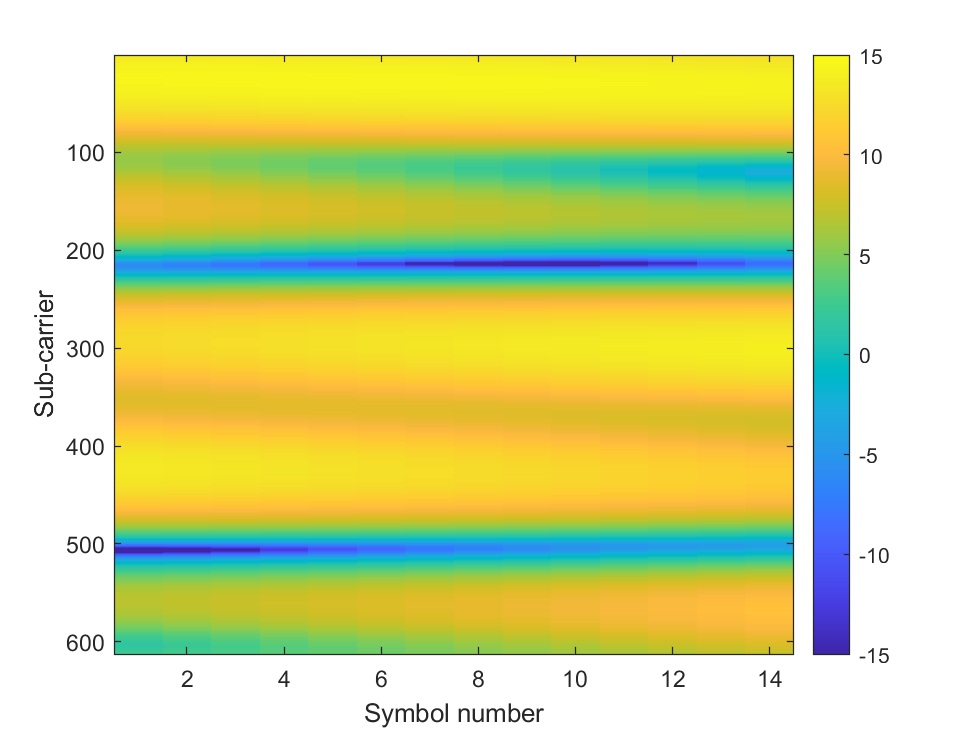

% Channel tap parameters
gain = [0, -3, -5]';         % Relative gain in dB
fd = [0, 100, -70]';         % Doppler shift in Hz
dly = [0, 200e-9, 500e-9]';  % Delay in seconds

% Create the channel
EsN0Avg = 10;
fdchan = FDChan(carrierConfig, 'gain', gain, ...
    'fd', fd, 'dly', dly, 'EsN0Avg', EsN0Avg);

% Get the CSI-RS indices and symbols for one slot
slotNum = 0;
frameNum = 0;
carrierConfig.NSlot = slotNum;
carrierConfig.NFrame = frameNum;
[csiInd, csiInfo] = nrCSIRSIndices(carrierConfig,csirs,'OutputResourceFormat','cell');
csiSym = nrCSIRS(carrierConfig,csirs,'OutputResourceFormat','cell');

% Create the TX grid and populate with the CSI-RS symbols
numPorts = 1;
txGrid = nrResourceGrid(carrierConfig,numPorts);
ncsi = length(csirs.CSIRSType);
for icsi = 1:ncsi    
    txGrid(csiInd{icsi}) = csiSym{icsi};    
end

% Run the TX grid through the channel
[rxGrid,chanGrid,noiseVar] = fdchan(txGrid, frameNum, slotNum);

% Compute the true channel SNR
snr = 10*log10(abs(chanGrid).^2/noiseVar);
clf;
imagesc(snr, [-15 15]);
colorbar();
xlabel('Symbol number');
ylabel('Sub-carrier');

## Estimating the Average SNR from the ZP and NZP CSI-RS

We first try to estimate the SNR from the ZP and NZP CSI-RS:

- We use the ZP CSI-RS to estimate the noise

- We use the NZP CSI-RS to estimate the  signal power

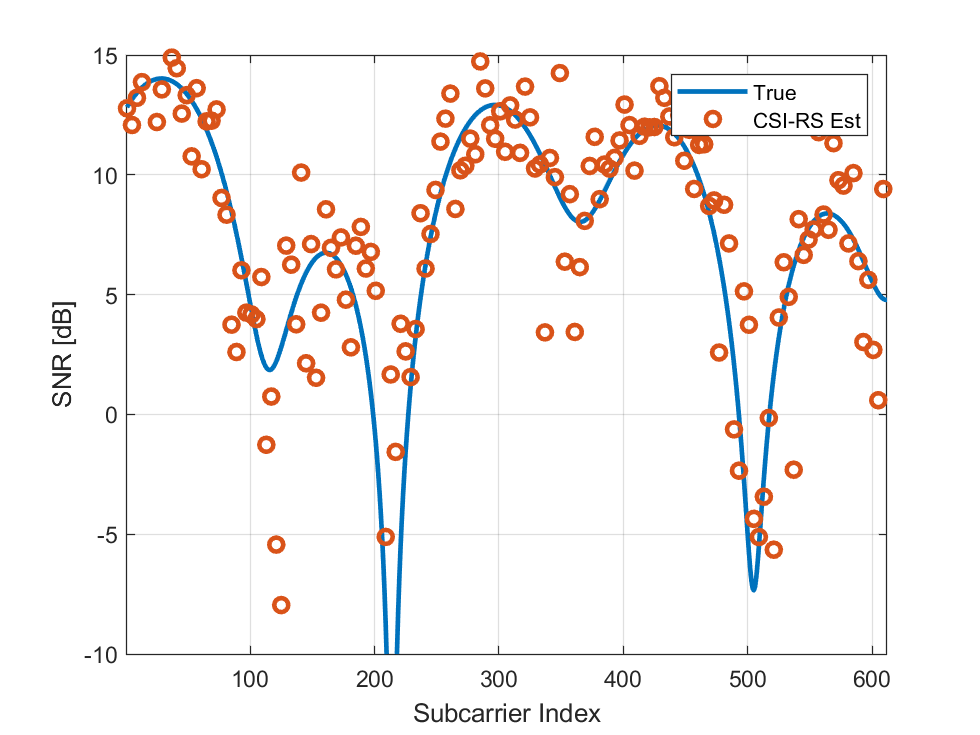

ncsi = length(csirs.CSIRSType);

for icsi = 1:ncsi
    % Get the symbols for CSI RS
    ycsi = rxGrid(csiInd{icsi});
    
    if strcmp(csirs.CSIRSType{icsi}, 'zp')
        % For zero-power CSI-RS, estimate the noise
        noiseEst = mean(abs(ycsi).^2);        
        
    else
        % For non-zero power CSI-RS, estimate the channel+noise
        xcsi = txGrid(csiInd{icsi});
        ycsi = rxGrid(csiInd{icsi});
        hestCsi = ycsi./xcsi;
        
        % Remember the index for NZP CSI-RS
        inzp = icsi;
    end
end


% Get the true SNR on the NZP CSI-RS
isym = csirs.SymbolLocations{inzp};
h = chanGrid(:,isym);
snr0 = 10*log10(abs(h).^2/noiseEst);

% Get the SNR per sub-carrier
nsc = length(snr0);
snrEst = 10*log10(abs(hestCsi).^2/noiseEst);

% Get the indices of the sub-carriers on which these estimates are
scInd = mod(csiInd{inzp}, nsc);

% Plot the results
clf;

plot(1:nsc, snr0, 'LineWidth', 2);
hold on;
plot(scInd, snrEst, 'o', 'LineWidth', 2);
grid on;
hold off;
xlabel('Subcarrier Index');
ylabel('SNR [dB]');
xlim([1,nsc]);
ylim([-10, 15]);

legend('True', 'CSI-RS Est');

We see that per sub-carrier, the estimate is quite noisy.  But, when we average, we get a close estimate.

snrTrue = 10*log10(mean(abs(chanGrid).^2, 'all')/noiseVar);
snrAvgEst = 10*log10((mean(abs(hestCsi).^2)-noiseEst)/noiseEst);

fprintf(1,'Estimated SNR = %7.2f dB\n', snrAvgEst);

Estimated SNR =    9.45 dB


fprintf(1,'True SNR = %7.2f dB\n', snrTrue);

True SNR =   10.00 dB


For computing capacity, it is sometimes better to estiamte the average mutual information or, equivalently, the theoretical spectral efficiency.

seTrue = mean(log2(1 + abs(chanGrid).^2/noiseVar),'all');
seEst = mean(log2(1 + abs(hestCsi).^2/noiseEst),'all');

fprintf(1,'Estimated MI = %7.2f\n', seEst);

Estimated MI =    2.96


fprintf(1,'True MI = %7.2f\n', seTrue);

True MI =    3.01


## Estimating the SNR with only NZP CSI-RS

The above method use separate ZP and NZP CSI-RS.  However, you can generally get a good CSI estimate in this simple case with the NZP estimate.  We use the function at the end of the file.

snrAvgEst1 = nzpCsiEst(hestCsi);

fprintf(1,'Est SNR w/ ZP       = %7.2f dB\n', snrAvgEst);

Est SNR w/ ZP       =    9.45 dB


fprintf(1,'Est SNR w/ only NZP = %7.2f dB\n', snrAvgEst1);

Est SNR w/ only NZP =   10.03 dB


fprintf(1,'True SNR = %7.2f dB\n', snrTrue);

True SNR =   10.00 dB


## In-Class Exercise:  Tracking CSI  over Time

We conclude by showing how to track the channel CSI over time.  

First, we configure the CSI-RS to use only the NZP CSI-RS with the same parameters as above

csirs = nrCSIRSConfig();
csirs.CSIRSType = {'nzp'};

% TODO:  Complete the remaining parameters as above
%   csirs.CSIRSPeriod = ...

To make the problem interesting, we will look at a flat fading channels with a Jake's spectrum.  Note that in this case the delay spread is zero, so the channel has no variation over frequency.  If there is variation, in general, the average SNR does not change much from one slot to the next.

npath = 10;            % Number of paths
aoaDispersion = 360;   % angular dispersion
gain = zeros(npath,1);  % Equal gain paths
dly = zeros(npath,1);  % No delay variations

% Doppler on each path determined by a random AoA
fdmax = 20;            % maximum Doppler
theta = rand(npath,1)*aoaDispersion;
fd = fdmax*cos(deg2rad(theta));

% Create the channel object
EsN0Avg = 10;
fdchan = FDChan(carrierConfig, 'gain', gain, 'fd', fd, 'dly', dly, 'EsN0Avg', EsN0Avg);

We now simulate the channel over 100 slots.  Complete the following code.

% Simulation time
nslotsPerFrame = waveformConfig.SlotsPerFrame;
nslots = 100;
nports = 1;

snr = zeros(nslots,1);
snrEstAvail = zeros(nslots,1);
snrEst = zeros(nslots,1);
for islot = 1:nslots
    
    % Get the slot and frame number
    slotNum = mod(islot, nslotsPerFrame);    
    frameNum =  floor(islot/nslotsPerFrame);
    
    % TODO:  Set slot and frame number in carrierConfig.NSlot and NFrame
    %   carrierConfig.NSlot = ...
    %   carrierConfig.NFrame = ...
 
    % TODO:  Get CSI indices and symbols for the slot
    %   [csiInd, csiInfo] = ...
    %   csiSym = ....
    
    % TODO:  Create a txGrid for the slot and populate it with the CSI-RS symbols. 
    %    txGrid = ...
    
    % TODO:  Generate the channel for the slot
    %    [...] = fdchan(...)   
    
    % TODO:  Measure the true average SNR in the slot from chanGrid and the noiseVar.
    % Convert to dB.  
    %    snr(islot) = ...
    
    
    icsi = 1;
    if ~isempty(csiInd{icsi})
        %  TODO:  If there are CSI-RS resources in the slot, estimate the
        %  SNR and mark the slot as having an snr estimate.
        %    snrEst(islot) = ...
        %    snrEstAvail(islot) = 1;
               
    end
            
end



We plot the true SNR and the estimates at the CSI-RS periods.  Label the x-axis in time in ms and the y-axis in dB.

% TODO


function snrAvgEst = nzpCsiEst(hestCsi)
    % NZP CSI-RS estimate
    % The CSI-RS symbols are grouped into navg symbols.  In each group k, we
    % estimate the average channel havg(k), and the noise.  Then, we
    % compute the average noise and average channel power across all the
    % groups.  There are corrrection factors for bias.
   
    
    % Number of REs to average over 
    navg = 3;
    nblks = floor(length(hestCsi)/navg);
    hestMat = reshape(hestCsi(1:navg*nblks), navg, nblks);
    
    % Average the results in each group
    havg = mean(hestMat,1);
    noiseEst = navg/(navg-1)*mean(abs(hestMat - havg).^2, 'all');
    
    % Signal power esimate removing the noise in the band.
    sigEst = max(0, mean(abs(havg).^2) - noiseEst/navg);
    
    % Get the aveage SNR. There is a minimum to prevent very low numbers.
    snrAvgEst = 10*log10(max(1e-3, sigEst / noiseEst));
end